# Physics 434 Lab 1

## Natalie Shen

### Problem 1

#### A)

Normal distribution is the most common continous probability distribution method that shows the probability of the occurance of specific data results within an array. It is most well know for its bell curve in the center that represents the mean.

#### B)

Here we will be integrating the normal standard distribution using erfc() to gain the probability of an array of numbers in a regular setting

x = [1 2.7 3]

x =     1.0000    2.7000    3.0000


Y = 1 - erfc(x)

Y =     0.8427    0.9999    1.0000


#### C)

We will be getting the inverse to recieve the z value, or sigma, or the data set using erfcinv()

z = 1 - erfcinv(Y)

z =     0.8597    0.9999    1.0000


mu = 0;
sigma = 1

sigma = 1

p = makedist("Normal", "mu", mu, "sigma",sigma);

p =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


x = linspace (-10, 10, 100);

x =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


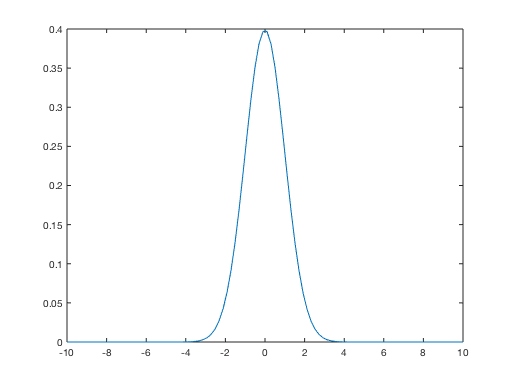

plot(x,pdf(p,x),"LineWidth",.5)

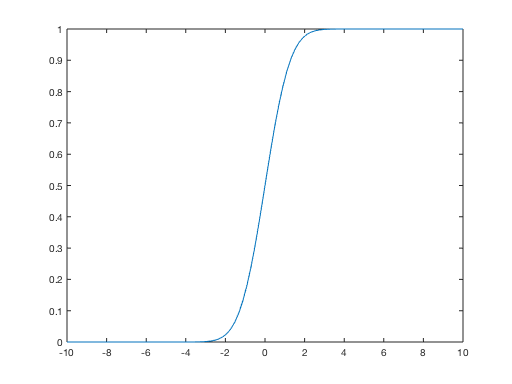

plot(x,normcdf(x,mu,sigma))

#### D)

The minus sigma (assumign we're still recording sigma from the center) means that the data being used is below average. The probabiity is equal to its positive sigma counterpart

### Problem 2

#### A)

Lognormal distribution is a continous probability distribution of a vector/function/variable who's logarith is normally distributed

#### B)

sigma = 1

sigma = 1

pd = makedist('Lognormal','mu',log(100000),'sigma',sigma)

pd =   LognormalDistribution

  Lognormal distribution
       mu = 11.5129
    sigma =       1



x = linspace(0,500000,100)

x = 	1.0e+05 *

         0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


y = pdf(pd,x)

y = 	1.0e+-5 *

         0    0.0916    0.2853    0.4438    0.5496    0.6128    0.6455    0.6572    0.6549    0.6432    0.6255    0.6042    0.5807    0.5562    0.5313    0.5067    0.4826    0.4593    0.4368    0.4154    0.3949    0.3755    0.3571    0.3396    0.3231    0.3075    0.2927    0.2788    0.2657    0.2533    0.2415    0.2304    0.2200    0.2101    0.2007    0.1919    0.1835    0.1756    0.1681    0.1610    0.1542    0.1478    0.1418    0.1360    0.1305    0.1253    0.1204    0.1157    0.1112    0.1069


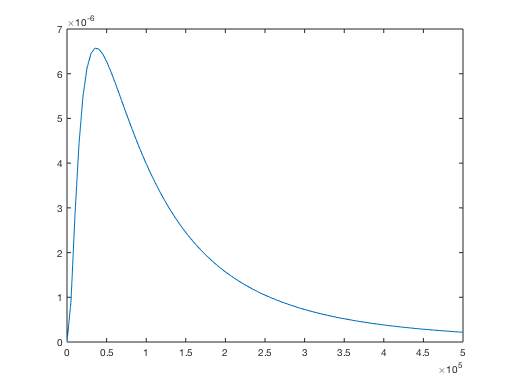


plot(x,y)

### Problem 3

#### A)

The random hypothetical measurement that will be used is 10.

### B)

What is the probability that the value 10 will be signal free?

### C)

x = 0:.1:10;
mu = 0;
sigma = 1;
p = logncdf(x,mu,sigma)

p =          0    0.0107    0.0538    0.1143    0.1798    0.2441    0.3047    0.3607    0.4117    0.4580    0.5000    0.5380    0.5723    0.6035    0.6317    0.6574    0.6808    0.7022    0.7217    0.7395    0.7559    0.7709    0.7848    0.7976    0.8093    0.8202    0.8303    0.8397    0.8484    0.8565    0.8640    0.8711    0.8776    0.8837    0.8895    0.8949    0.8999    0.9046    0.9091    0.9132    0.9172    0.9209    0.9244    0.9277    0.9308    0.9337    0.9365    0.9391    0.9416    0.9440


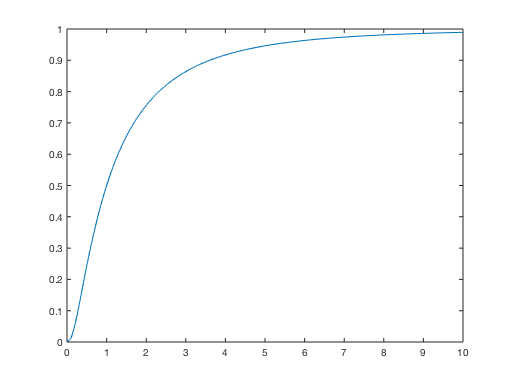


plot(x,p)


m = 10;
pm = logncdf(m,mu,sigma)

pm = 0.9893

#### D)

As calculated, the probability for the value 10 is 0.9893

#### E)

sm = norminv(pm,0,1)

sm = 2.3026

### Noncontinious

#### A)

For this section, I'll be using binomial distribution

Binomial distribution is a type of discrete distribution that uses number of trials and boolean outcomes (yes/no, true/false, etc).

#### B)

First graph is the control graph, following graphs are test ones that have a different parameter than the control.

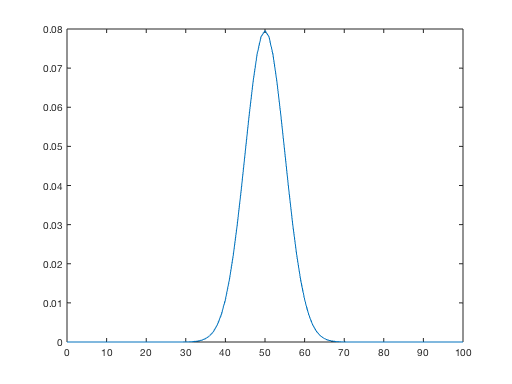

x = 0:100;
y = binopdf(x,100,.5);
plot(x,y)

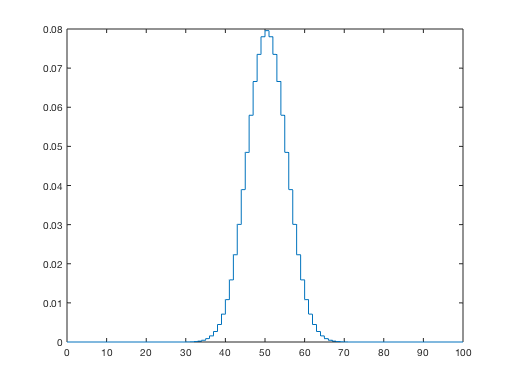

stairs(x,y)

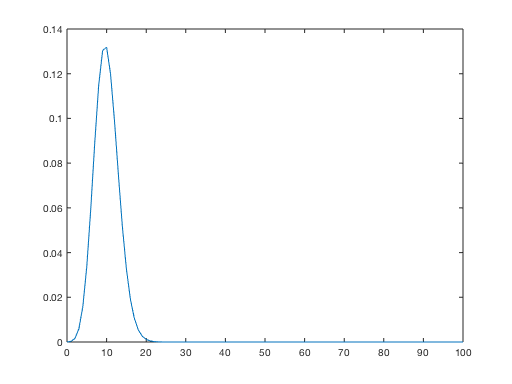


x = 0:100;
y = binopdf(x,100,.1);
plot(x,y)

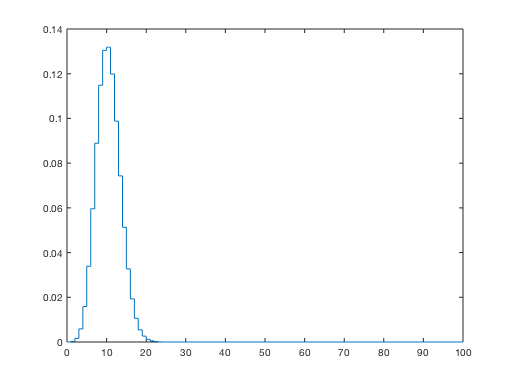

stairs(x,y)

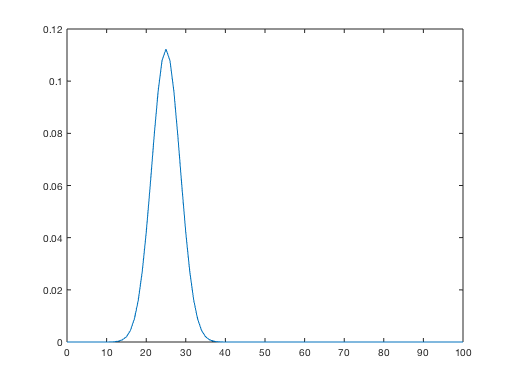


x = 0:100;
y = binopdf(x,50,.5);
plot(x,y)

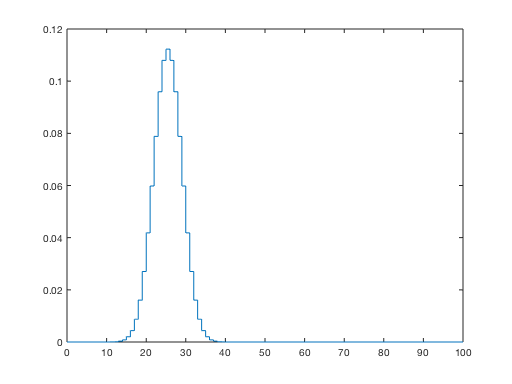

stairs(x,y)

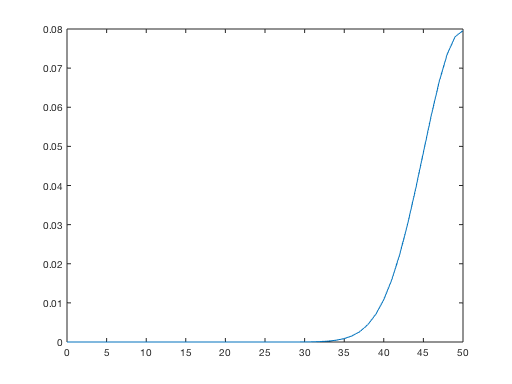


x = 0:50;
y = binopdf(x,100,.5);
plot(x,y)

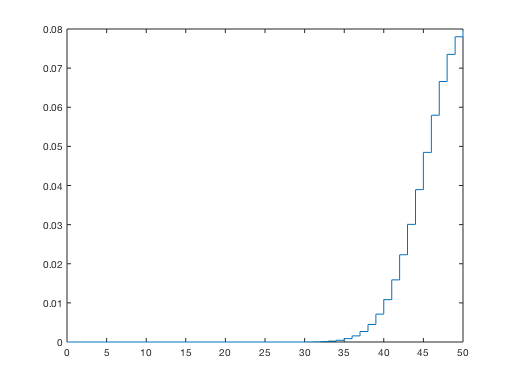

stairs(x,y)

#### C)

Question: What is the probability of a student getting a 70% on a test where the average is 63.5%?

x = 0:100

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


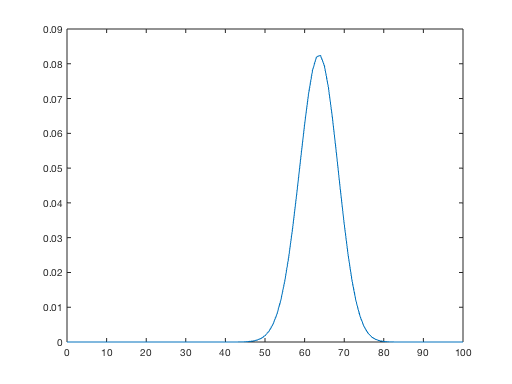

y = binopdf(x,100,.635);

plot(x,y)

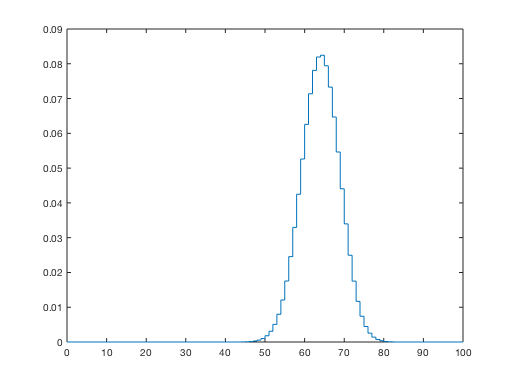

stairs(x,y)


p = binopdf(70,100,.635)

p = 0.0340

#### D)

Discrete distributions may serve mainly to generalize and simplify predictions and probability

#### E)

Having a strange mean is not outlandish as results from many trials wield various results that often doesn't result a whole number. Depending on how inaccurate/accurate the data is; how many trials, parameters, etc will change the probability and the binomial distribution.